shifted_histogram=zeros(1,256); % shift 2 channels from spc.lifetimes{1,1}

% spc.lifetimes 1:8 is 0, 249:256 is 0

for i=11:248
    shifted_histogram(i)=spc.lifetimes{1,1}(i-2);
end

shifted_histogram(9)=spc.lifetimes{1,1}(247);
shifted_histogram(10)=spc.lifetimes{1,1}(248);

spc_openCurves('/Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/AMAKARPHYS001/AMAKARPHYS001FLIMFLIM030.mat',1)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/AMAKARPHYS001/AMAKARPHYS001FLIMFLIM030.mat


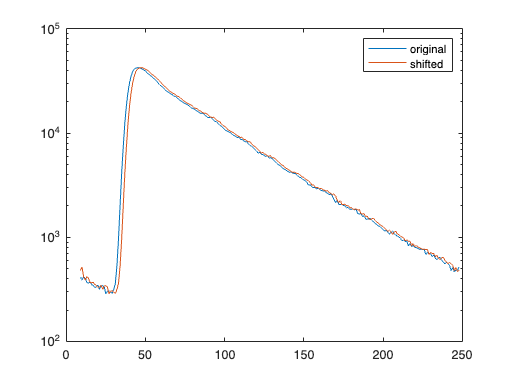

figure
semilogy(spc.lifetimes{1,1})
hold on
semilogy(shifted_histogram)
legend('original','shifted')

lft_steps=(1:1:256)*12.5/256;
weight_n_lft=lft_steps.*spc.lifetimes{1,1};
empirical_lft1=sum(weight_n_lft)/sum(spc.lifetimes{1,1})

empirical_lft1 = 3.8978


lft_steps=(1:1:256)*12.5/256;
weight_n_lft=lft_steps.*shifted_histogram;
empirical_lft2=sum(weight_n_lft)/sum(shifted_histogram)

empirical_lft2 = 3.9897


empirical_lft2-empirical_lft1

ans = 0.0919

(empirical_lft2-empirical_lft1)/(12.5/256)

ans = 1.8815

% do fitting for the original histogram
dpt1=spc.fits{1,1}.beta5

dpt1 = -0.0708

spc.lifetimes{1,1}=shifted_histogram

spc = struct with fields:
         switchess: {[1×1 struct]  [1×1 struct]}
     GUI_switchess: [1×1 struct]
              fits: {[1×1 struct]}
          GUI_fits: [1×1 struct]
          filename: '/Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/AMAKARPHYS001/AMAKARPHYS001FLIMFLIM030.mat'
              GUIS: [1×1 struct]
          datainfo: [1×1 struct]
               fit: [1×1 struct]
          switches: [1×1 struct]
         imageMods: {[256×128×128 double]}
      originalFile: 'C:\Users\User\Desktop\Aditi\AMAKARPHYS001\AMAKARPHYS001FLIMFLIM030.mat'
           SPCdata: [1×1 struct]
    imageModSlices: {}
       maxProjects: {[]}
         lifetimes: {[0 0 0 0 0 0 0 0 480 518 416 387 417 406 370 363 372 351 346 330 333 348 316 341 343 333 286 305 307 296 290 316 361 528 960 2011 4120 7368 12433 18436 24631 30595 35372 39019 41091 41978 42391 42231 41753 40980 40151 39296 … ]}
              size: [256 128 128]
          projects: {[128×128 double]}


dpt2=spc.fits{1,1}.beta5

dpt2 = -0.1687

dpt2-dpt1

ans = -0.0979